# Exploring Sequences

## Introduction

In this activity we will explore sequences $\{a_n\}$ geometrically and symbolically. 

First, we will use the command [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html) to plot sequences and try to determine whether they converge or diverge. Then we will calculate the limit of particular sequences using the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html).

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

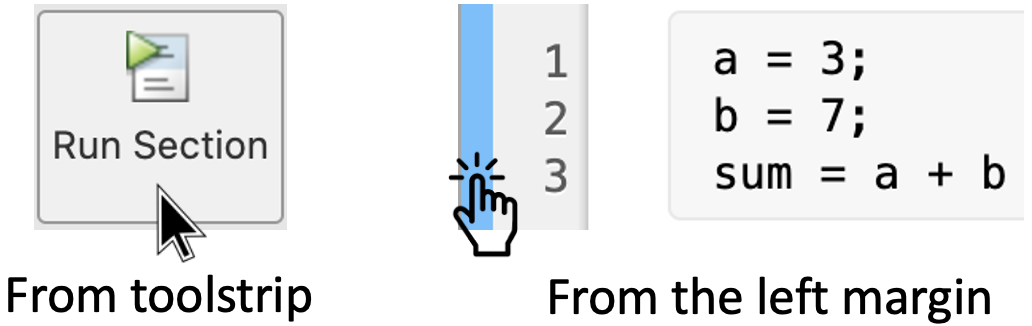

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Geometric exploration

### 1.1 Setting up

Consider the following sequences

a) $a_n =\sin \left({\left(-2\right)}^n \right)$  and    b) $b_n =\frac{2n^3 }{n^3 -4}$ .

To plot these sequences, first, let's create a variable:

n_last = 50

n_last = 50

This variable is an integer defined between 1 and 150.

We need to use the colon operator (:) to define the domain of the sequences. In this case we can store this information as a variable:

n = 1:n_last

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Now we can define our sequences as follows:

an = sin((-2).^n)

an =    -0.9093   -0.7568   -0.9894   -0.2879   -0.5514    0.9200   -0.7210   -0.9992   -0.0795   -0.1585    0.3131   -0.5946    0.9562   -0.5599   -0.9279    0.6921    0.9991   -0.0841   -0.1676    0.3305   -0.6238    0.9751   -0.4322   -0.7796    0.9765    0.4208    0.7634   -0.9862   -0.3266   -0.6173    0.9713   -0.4620   -0.8195    0.9393    0.6444    0.9855   -0.3339   -0.6295    0.9783   -0.4057   -0.7416    0.9950    0.1991    0.3902   -0.7185    0.9995    0.0649    0.1295   -0.2568    0.4964


bn = (2 * n.^3)./(n.^3 - 4)

bn =    -0.6667    4.0000    2.3478    2.1333    2.0661    2.0377    2.0236    2.0157    2.0110    2.0080    2.0060    2.0046    2.0036    2.0029    2.0024    2.0020    2.0016    2.0014    2.0012    2.0010    2.0009    2.0008    2.0007    2.0006    2.0005    2.0005    2.0004    2.0004    2.0003    2.0003    2.0003    2.0002    2.0002    2.0002    2.0002    2.0002    2.0002    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001    2.0001


**Remark:** Here we are using row vectors (also known as *arrays*) which means that the operations *multiplication*, *division* and *exponentiation* must have the *period *"`.`" before each operator: `*, /, ^`. Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

### 1.2 Plotting sequences

Finally, we plot each sequence separately:

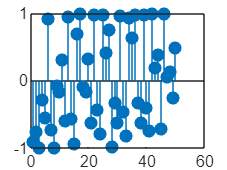

stem(n, an, 'filled')

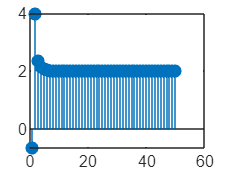

stem(n, bn, 'filled')

Drag the slider of the variable `max` defined in section 1.1 to show more terms of the sequences on the plots.

### 1.3 Compare sequences

You can compare the sequences by plotting them together as follows:

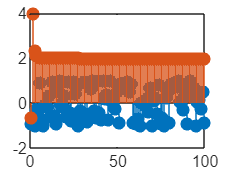

m = 1:100;
cm = sin((-2).^m);
dm = (2 * m.^3)./(m.^3 - 4);
stem(m, cm,'filled')
hold on
stem(m, dm,"filled")
hold off

**Remark:** We used the command "[hold on](https://au.mathworks.com/help/matlab/ref/hold.html)" to plot multiple stem graphs on the same figure.

Based on the graphs of the sequences, which one converges? Which one diverges?

## 2. Symbolic exploration

### 2.1 Calculating limits symbolically

Calculating limits of sequences in MATLAB is quite easy. We just need the command [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html). For example, let's calculate the limit of

${c_n =\left(\frac{2n-3}{3n-7}\right)}^4$.

Here we need to create a *symbolic variable* for "`n`", that is:

syms n

Then we just calculate the limit as follows:

limit(((2*n-3)/(3*n-7))^4, n, inf)

$$ans = \frac{16}{81}$$

### 2.2 Comparing results

We will calculate the limits of $a_n =\sin \left({\left(-2\right)}^n \right)$ and $b_n =\frac{2n^3 }{n^3 -4}$.

But before running the code in this section, remember the behaviour of these sequences based on the plots we have made previously. Pause and think about what the limit of each of them would be. Once you have done this, run the following lines:

ans1 = limit(sin((-2)^n), n, inf)          % limit of sequence a_n

$$ans1 = \lim_{n\to \infty }\sin\left({\left(-2\right)}^{n}\right)$$

ans2 = limit((2 * n^3)/(n^3 - 4), n, inf)  % limit of sequence b_n

$$ans2 = 2$$

What do you notice? What happens to the results `ans1` and `ans2`? Can you confirm the results using the theorems covered in class?

## 3. Hands on practice

Let's practice what we just learned. 

### Activity 1:

Use the commands [`linspace`](https://au.mathworks.com/help/matlab/ref/linspace.html) and [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html) to plot 150 terms of the following sequences.

- 
$$\frac{2^k +1}{e^k }$$


- 
$$2+\cos \left(k\;\pi \right)$$


- 
$${\left(-2\right)}^{k+1}$$


- 
$$\frac{\sin \left(k+\pi \right)}{k^3 }$$


- 
$$\cos \left(3\pi \;k\right)\cdot \sin \left(2\pi \;k\right)$$


Analyse the plots of each sequence. What do you notice? Can you determine whether the sequence converges or diverges based on the information provided by its plot?

Write your code here:

syms k

limit((2^k +1)/exp(k), k, inf)

$$ans = 0$$


limit(2 + cos(k*pi), k, inf)

$$ans = \mathrm{NaN}$$


limit((-2)^(k+1), k, inf)

$$ans = \mathrm{NaN}$$


limit((sin(k+pi)/k^3), k, inf)

$$ans = 0$$


limit(cos(3*pi*k) * sin(2*pi*k))

$$ans = 0$$

**Hint 1:** In this case you have to define a variable `k`. Also check the previous examples to correctly type the syntax of the arithmetic operations.

**Hint 2:** In MATLAB the constant $\pi$ is defined as `pi`. The constant $e\approx 2\ldotp 71828$ can be defined using the function [`exp()`](https://au.mathworks.com/help/matlab/ref/exp.html), that is, `exp(1)`.

### Activity 2:

Find the limits of each sequence in your notebook and then using the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html). Do the results agree with the plots from Activity 1?

Yes




**Hint 3:** To add comments to MATLAB code, use the percent (`%`) symbol. Comment lines can appear anywhere in a program file, and you can append comments to the end of a line of code.